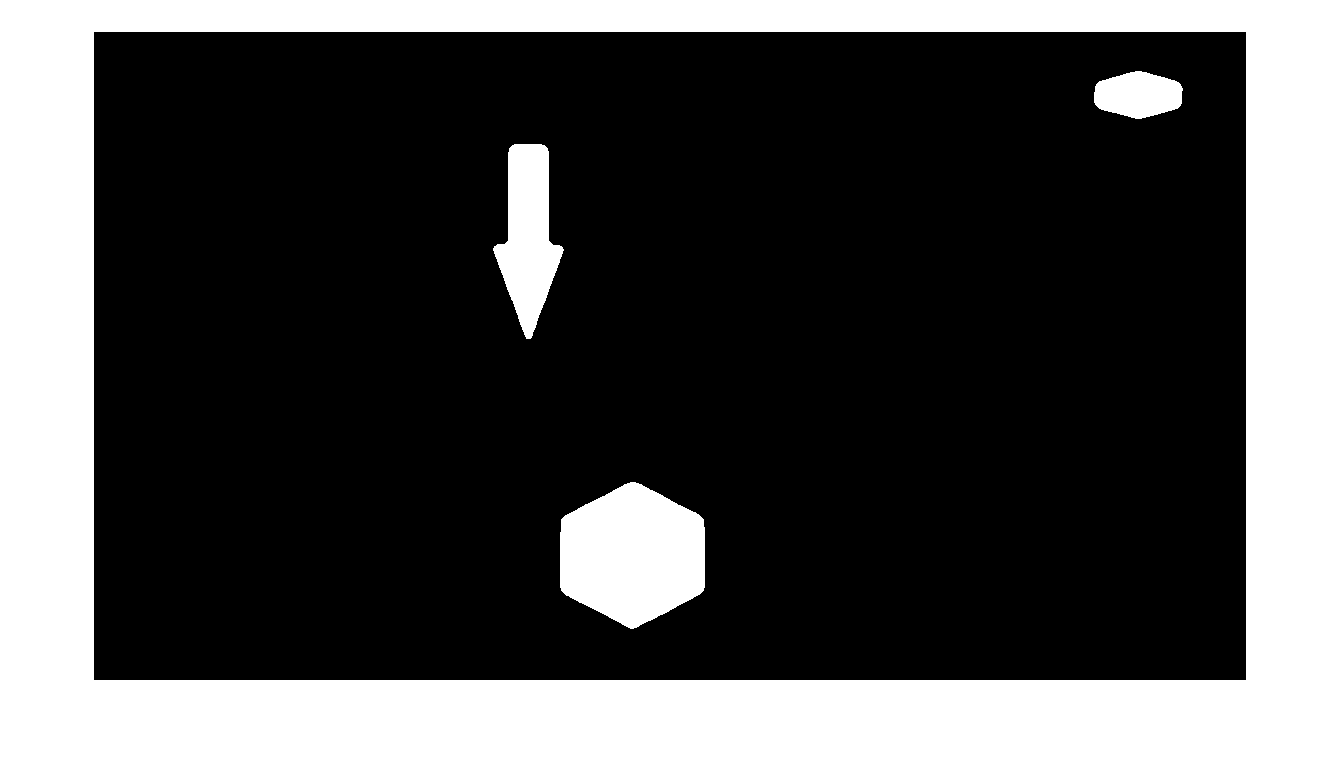

clear all;
close all;
clc;

a=imread("C:\Users\Admin\Desktop\imgtest2.jpg");
grayscale=rgb2gray(a);

r=a(:,:,1);
g=a(:,:,2);
b=a(:,:,3);

c=g-grayscale;
c=im2bw(c,0.2);
c=medfilt2(c,[10 10]);
imshow(c);

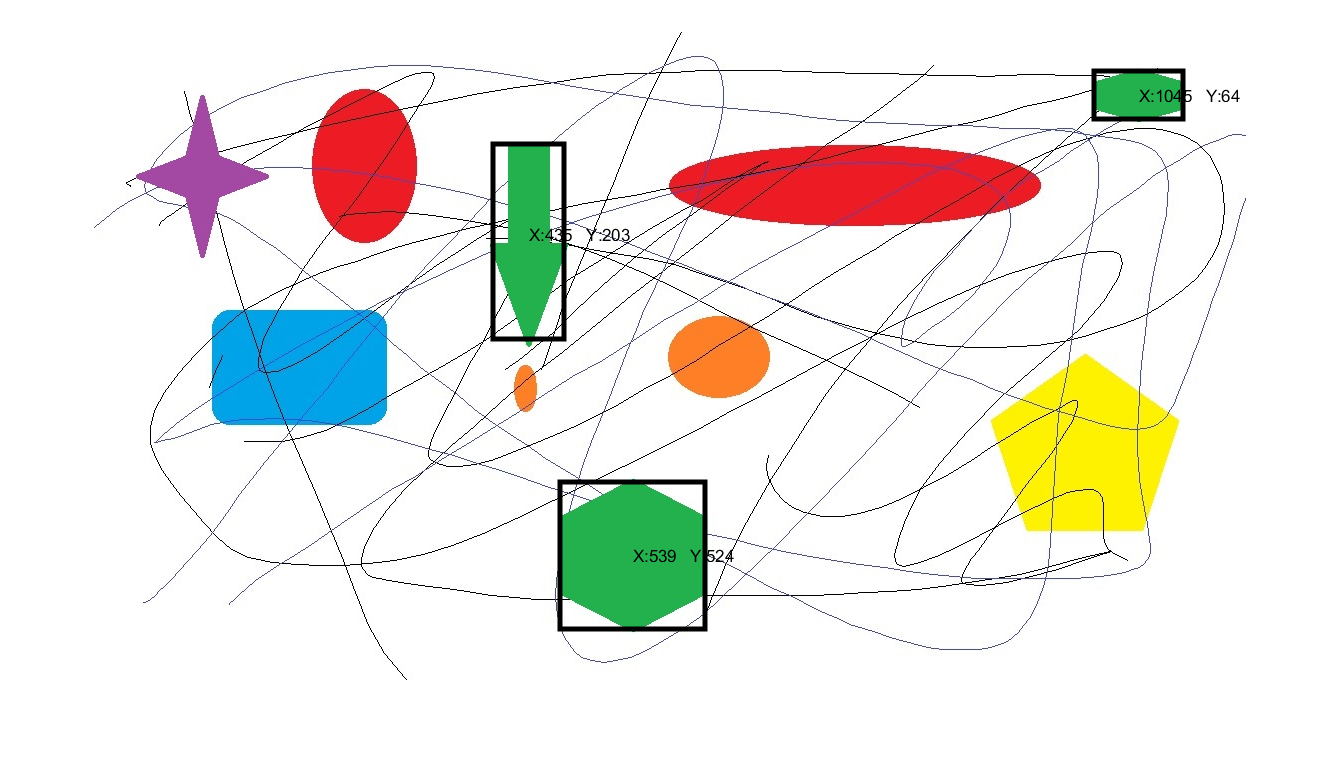


stat=regionprops(c,'BoundingBox','Centroid');

imshow(a);
hold on;

for i=1:length(stat)
    pos=stat(i).BoundingBox;
    rectangle('Position',pos,'LineWidth',3);
    cent=round(stat(i).Centroid);
    text(cent(1),cent(2),strcat("X:",num2str(cent(1)),"   Y:",num2str(cent(2))));
end

hold off;

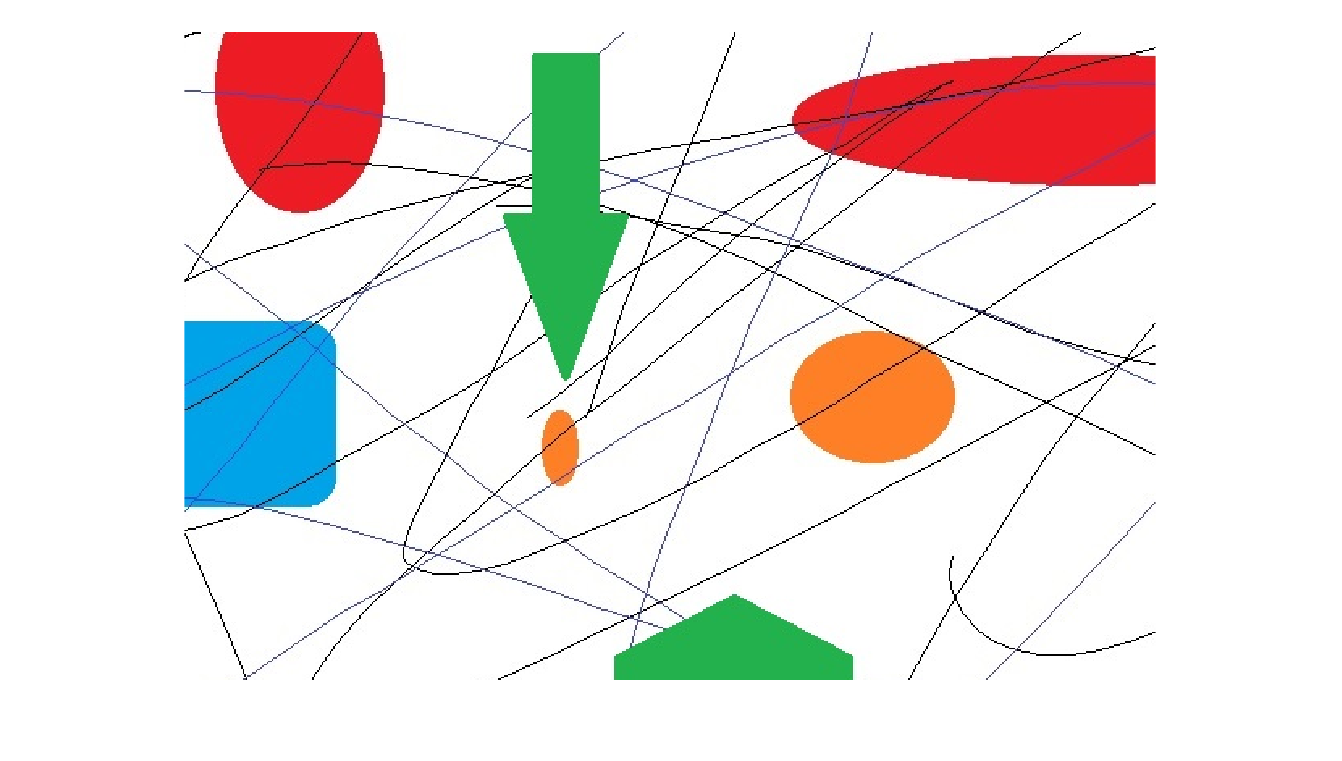


crop=a(100:500,200:800,:);
imshow(crop);